# MA 423 Matrix Computations                    Lab - 8

## Name: Rasesh Srivastava

## Roll number: 210123072

format long e

## Question 1

Example 1:

n = 17;
m = 20;
A = rand(m, n);
[W, R] = polard1(A);
norm(W*R - A)

ans =      3.169905471450650e-14


norm(W'*W - eye(n))

ans =      3.514537395810398e-15


norm(R - R')

ans =      8.069228164677366e-16


max(imag(eig(R)))

ans =      0


min(eig(R))

ans =      1.590356871514811e-01


Example 2:

n = 30;
m = 23;
A = rand(m, n);
[W, R] = polard1(A);
norm(R*W - A)

ans =      5.119575792153279e-14


norm(W*W' - eye(m))

ans =      3.167172751189430e-15


norm(R - R')

ans =      8.239999616075767e-16


max(imag(eig(R)))

ans =      0


min(eig(R))

ans =      3.322679162519957e-01


Example 3:

n = 9;
m = 16;
A = rand(m, n);
[W, R] = polard1(A);
norm(W*R - A)

ans =      6.180389558389540e-14


norm(W'*W - eye(n))

ans =      2.591810269603273e-15


norm(R - R')

ans =      5.191649612808120e-16


max(imag(eig(R)))

ans =      0


min(eig(R))

ans =      4.413142061245041e-01


Hence, we can see that norm(W∗R − A) (or norm(R∗W − A)), norm(W'∗W − I), (or norm(W∗W' − I)), norm(R − R'), max(imag(eig(R))) are of the order of unit roundoff and min(eig(R)) is non-negative. 

#### When A is a n * n square matrix,

Example 1:

m = 27;
n = 27;
A = rand(m, n);
[W, R] = polard1(A);
norm(W*R - A)

ans =      9.239280225621996e-14


norm(W'*W - eye(m))

ans =      3.732190289892753e-15


norm(R - R')

ans =      1.058573800237467e-15


max(imag(eig(R)))

ans =      0


min(eig(R))

ans =      5.766673902105313e-02


norm(A'*A - R*R)

ans =      1.354411035497695e-12


Hence, we can see that norm(W∗R − A) (or norm(R∗W − A)), norm(W'∗W − I), (or norm(W∗W' − I)), norm(R − R'), max(imag(eig(R))) are of the order of unit roundoff and min(eig(R)) is non-negative. Also, norm(R*R - A'∗A) is of the order of unit roundoff, which shows that R^2 = A*A.

## Question 2

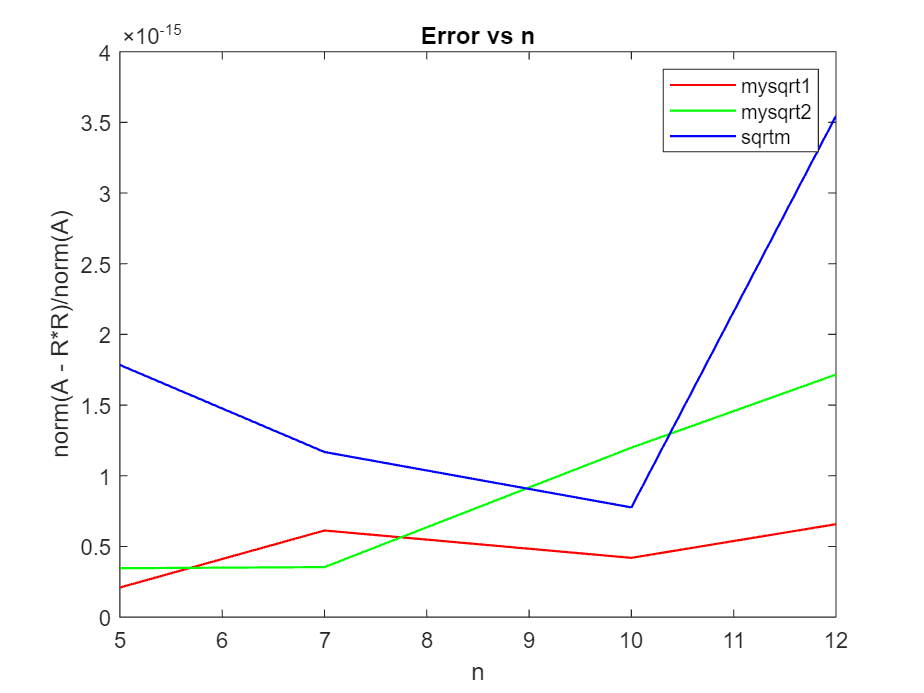

n = [5, 7, 10, 12];
[data1, data2, data3] = deal([]);
for i = n
    A = hilb(i);
    R1 = mysqrt1(A);
    R2 = mysqrt2(A);
    R3 = sqrtm(A);
    data1(end + 1) = norm(A - R1 * R1)/norm(A);
    data2(end + 1) = norm(A - R2 * R2)/norm(A);
    data3(end + 1) = norm(A - R3 * R3)/norm(A);
end
plot(n, data1, 'r', 'LineWidth', 1);
hold on;
plot(n, data2, 'g', 'LineWidth', 1);
hold on;
plot(n, data3, 'b', 'LineWidth', 1);
hold off;
xlabel('n');
ylabel('norm(A - R*R)/norm(A)');
title('Error vs n');
legend('mysqrt1', 'mysqrt2', 'sqrtm');

### Observations:

According to the plot, the relative error is almost always less for mysqrt1 function. Hence, it is reliable and better.

The relative error for mysqrt2 is almost always less than that of sqrtm.

## Question 3

#### Part 1: Checking the correctness of the function program polard2

Example 1:

n = 14;
m = 14;
A = rand(m, n);
[W, R] = polard2(A);
norm(R*W - A)

ans =      8.712885337046944e-16


norm(W'*W - eye(n))

ans =      1.582800925087879e-13


norm(R - R')

ans =      2.321369225990935e-15


max(imag(eig(R)))

ans =      0


min(eig(R))

ans =      1.051340251652144e-01


norm(A*A' - R*R)

ans =      3.086888983845943e-14


Example 2:

m = 9;
n = 9;
A = rand(m, n);
[W, R] = polard2(A);
norm(R*W - A)

ans =      5.067808605816173e-16


norm(W'*W - eye(m))

ans =      5.278621976153284e-13


norm(R - R')

ans =      1.151018055047613e-15


max(imag(eig(R)))

ans =      0


min(eig(R))

ans =      3.462550239125781e-02


norm(A*A' - R*R)

ans =      6.447311786669137e-15


Hence, we can see that (R∗W − A), norm(W'∗W − I), norm(R − R'), max(imag(eig(R))) are of the order of unit roundoff and min(eig(R)) is non-negative. Also, norm(R*R - A∗A') is of the order of unit roundoff, which shows that R^2 = AA*.

#### Part 2: Comparing polard1 and polard2 function programs and plotting the graph

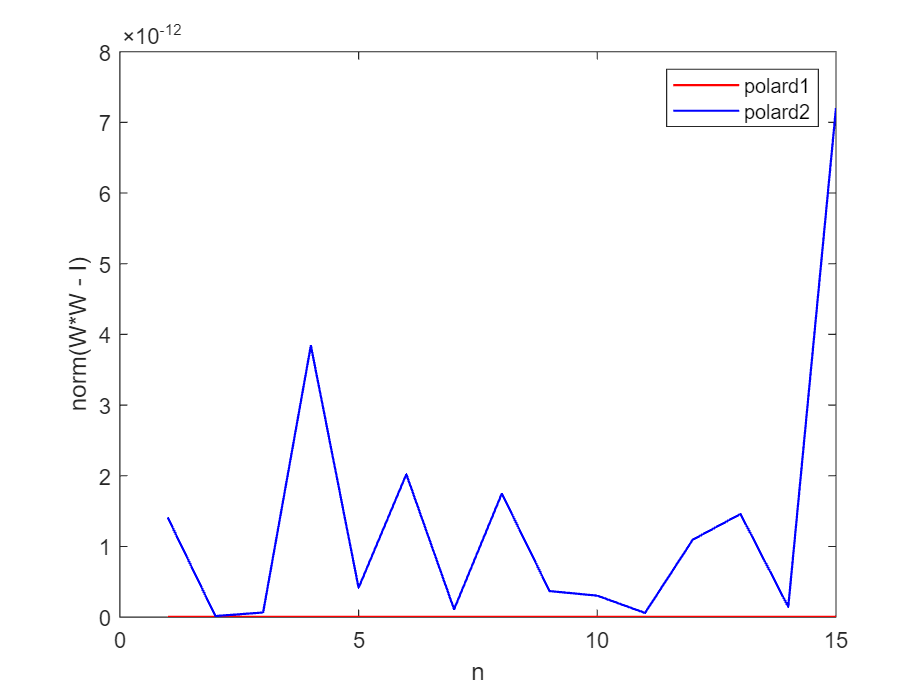

[n, sz] = deal(15, 20);
[data1, data2] = deal([]);
rng(9);
matrices = randn(sz, sz, n);
for j = 1 : n
   mat = matrices(:, :, j);
   [U, d, V] = svd(mat);
   d = sort(diag(d), 'descend');
   d = (d / d(end)) * (10^(-j + 6));
   d = diag(d);
   A = U * d * V';
   [W, R] = polard1(A);
   [X, T] = polard2(A);
   data1(end + 1) = norm(W' * W - eye(sz));
   data2(end + 1) = norm(X' * X - eye(sz));
end
x_range = (1:n);
plot(x_range, data1, 'r', 'LineWidth', 1);
hold on;
plot(x_range, data2, 'b', 'LineWidth', 1);
hold off;
xlabel('n');
ylabel('norm(W*W - I)');
legend('polard1', 'polard2');

### Observations:

It is clear that the polard1 is better and more reliable than polard2. The relative difference in both the methods is very high when compared to the norm difference parameter.

## Question 4

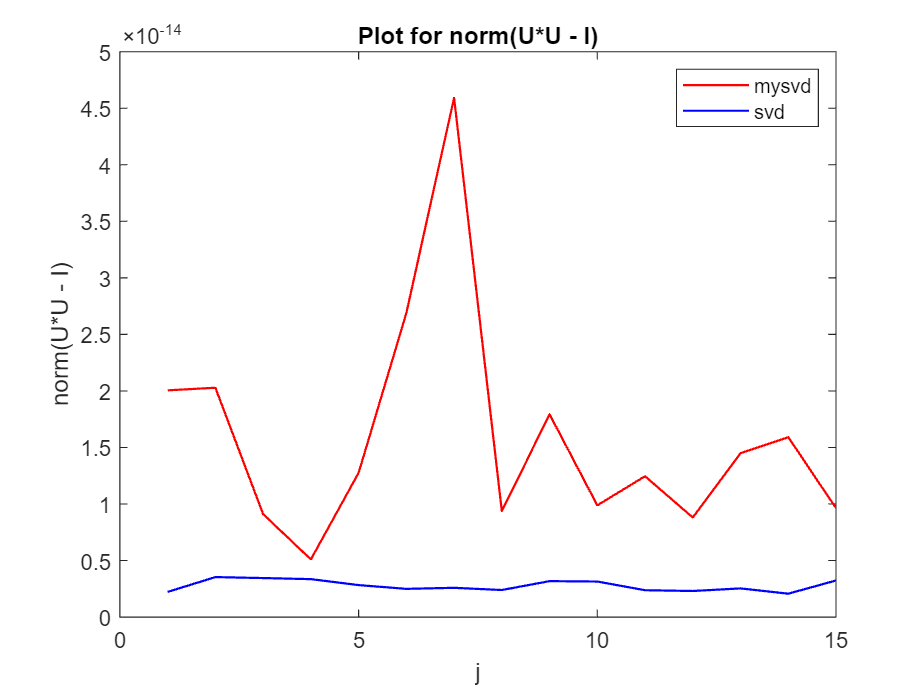

[n, sz] = deal(15, 20);
[data1, data2, data3, data4] = deal([]);
rng(42);
matrices = randn(sz, sz, n);
for j = 1 : n
   mat = matrices(:, :, j);
   [U, d, V] = svd(mat);
   d = sort(diag(d), 'descend');
   d = (d / d(end)) * (10^(-j + 6));
   d = diag(d);
   A = U * d * V';
   [U1, d1, V1] = mysvd(A);
   [U2, d2, V2] = svd(A);
   data1(end + 1) = norm(U1' * U1 - eye(sz));
   data2(end + 1) = norm(U2' * U2 - eye(sz));
   data3(end + 1) = norm(V1' * V1 - eye(sz));
   data4(end + 1) = norm(V2' * V2 - eye(sz));
end
x_range = (1:n);
figure();
plot(x_range, data1, 'r', 'LineWidth', 1);
hold on;
plot(x_range, data2, 'b', 'LineWidth', 1);
hold off;
xlabel('j');
ylabel('norm(U*U - I)');
title('Plot for norm(U*U - I)');
legend('mysvd', 'svd');

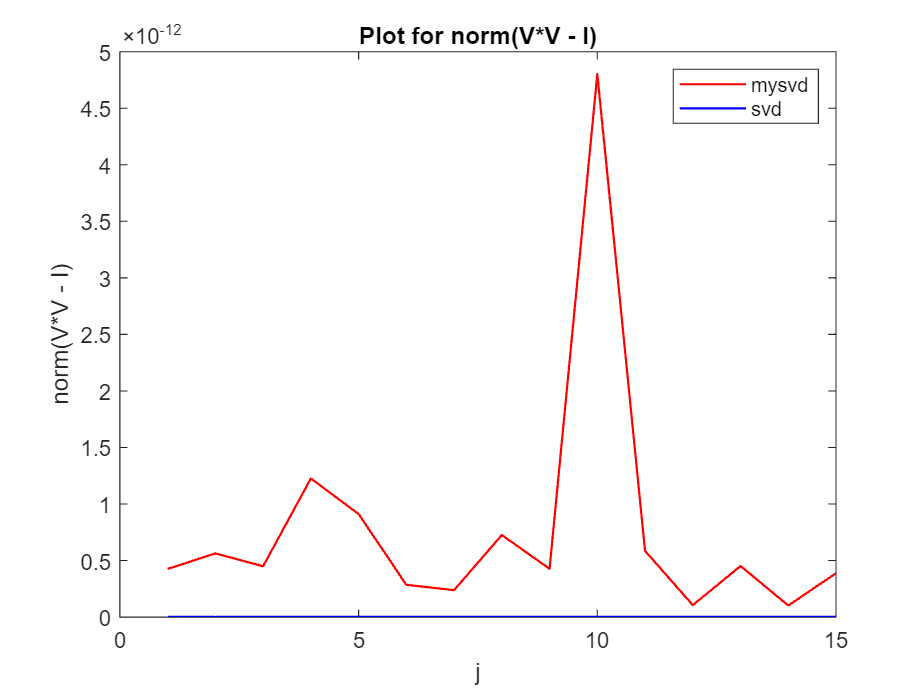

figure();
plot(x_range, data3, 'r', 'LineWidth', 1);
hold on;
plot(x_range, data4, 'b', 'LineWidth', 1);
hold off;
xlabel('j');
ylabel('norm(V*V - I)');
title('Plot for norm(V*V - I)');
legend('mysvd', 'svd');

### Observations:

It is evident from the plots that the inbuilt svd function is better than mysvd. The departure from orthogonality is more in matrices U and V when computed using mysvd than when computed using inbuilt svd function.

A = rand(3,3);
[U, S, V] = mysvd(A);
norm(A - U*S*V')

ans =      5.663027015177437e-16



[U, S, V] = svd(A);
norm(A - U*S*V')

ans =      8.604153410443596e-16


# Function Programs

## Question 1

function [W, R] = polard1(A)
    [m, n] = size(A);
    if m >= n    
        [U, d, V] = svd(A, 0);
        R = V * d * V';
        W = U * V';
    else
        [U, d, V] = svd(A, 'econ');
        R = U * d * U';
        W = U * V';
    end
end

## Question 2

function R1 = mysqrt1(A)
    [X, D] = eig(A);
    R1 = (X * sqrt(D)) / X;
end

function R2 = mysqrt2(A)
    R = chol(A);
    [U, d, V] = svd(R);
    R2 = V * d * V'; 
end

## Question3

function [W, R] = polard2(A)
    R = mysqrt1(A * A');
    W = R \ A;
end

## Question 4

function [U, S, V] = mysvd(A)
    [W, R] = polard2(A);
    [V, S] = eig(R);
    U = V;
    V = W'*V;
end